#                                                     Analisis de sistema caótico

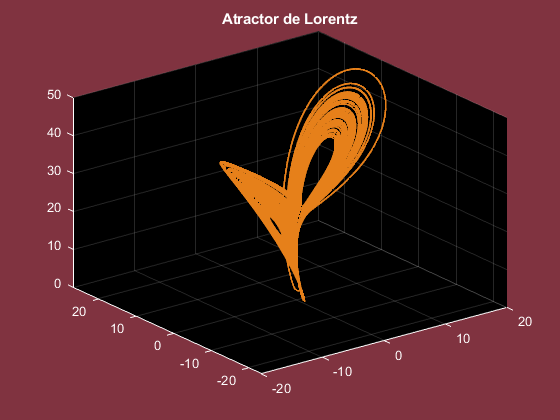

clc
clearvars
close all
format short
global sigma beta rho

sigma=10;
beta=8/3;
rho=28;

ti=0;
tf=100;
h=0.001;
t=(ti:h:tf);


x02=[0.7,0.3,2,0.3,0.7,0.4]; %Condiciones iniciales
[t,x1]=ode45(@DinamicaLorenz2,t,x02);


plot3(x1(:,1),x1(:,2),x1(:,3),'color',[0.9 0.5 0.1],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Atractor de Lorentz','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

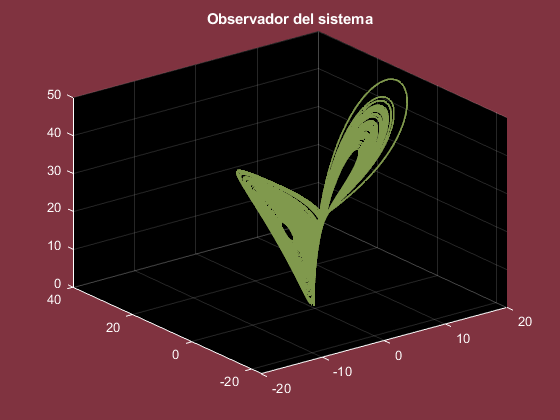


plot3(x1(:,4),x1(:,5),x1(:,6),'color',[0.5 0.6 0.3],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Observador del sistema','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

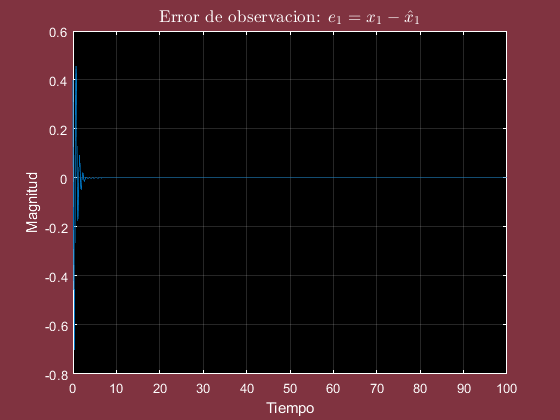



plot(t,x1(:,1)-x1(:,4))
title('Error de observacion: $e_{1}=x_{1}-\hat{x}_{1}$','interpreter','latex','color','w','FontSize',13) %Convergencia de x2 con su ecuacion del observador x2 gorro
ylabel('Magnitud')
xlabel('Tiempo')
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

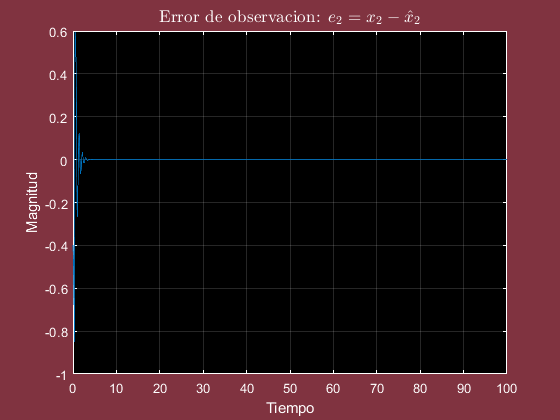


plot(t,x1(:,2)-x1(:,5))
title('Error de observacion: $e_{2}=x_{2}-\hat{x}_{2}$','interpreter','latex','color','w','FontSize',13) %Convergencia de x2 con su ecuacion del observador x2 gorro
ylabel('Magnitud')
xlabel('Tiempo')
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

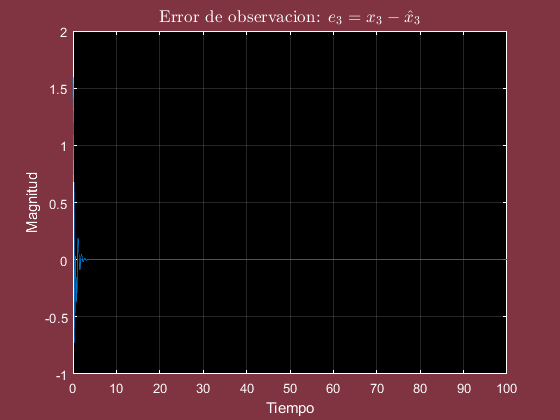



plot(t,x1(:,3)-x1(:,6))
title('Error de observacion: $e_{3}=x_{3}-\hat{x}_{3}$','interpreter','latex','color','w','FontSize',13)
ylabel('Magnitud')
xlabel('Tiempo')
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

                               Ahora se realiza el observador completo            

                                        

function xp=DinamicaLorenz2(t,x0)

global sigma beta rho

x=x0(1);
y=x0(2);
z=x0(3);
xg1=x0(4);
xg2=x0(5);
xg3=x0(6);

xp=[sigma*(y-x);
     x*(rho-z)-y;
     x*y-beta*z;
     sigma*(xg2-xg1); %ecuacion del observador
     rho*x-xg2-x*xg3; %ecuacion del observador
     -beta*xg3+x*xg2  %ecuacion del observador
     ];
end